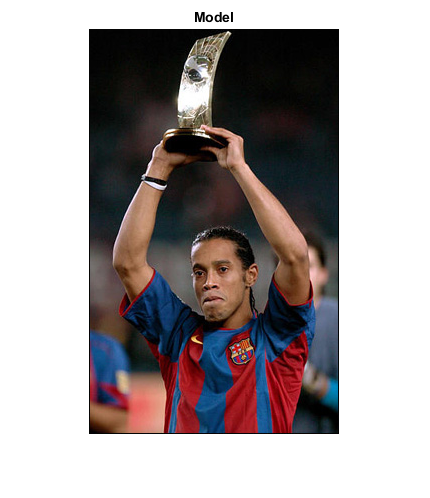

im = imread('model.jpg');
figure, imshow(im); title('Model');

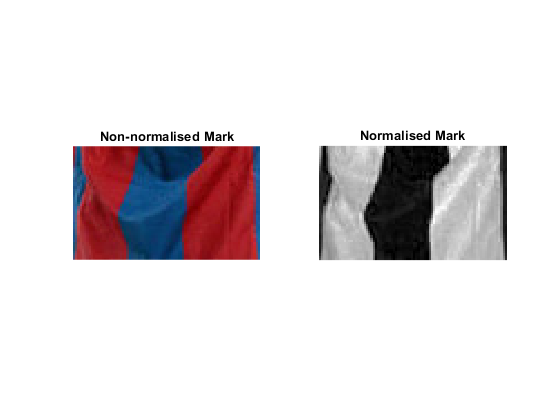


pattern = im(350:400,87:170,:);
figure, 
subplot(1,2,1);imshow(pattern); title('Non-normalised Mark');

imnorm = normalizeRGB(im);
pattnorm = imnorm(350:400,87:170,:);
subplot(1,2,2);imshow(pattnorm(:,:,1)); title('Normalised Mark');

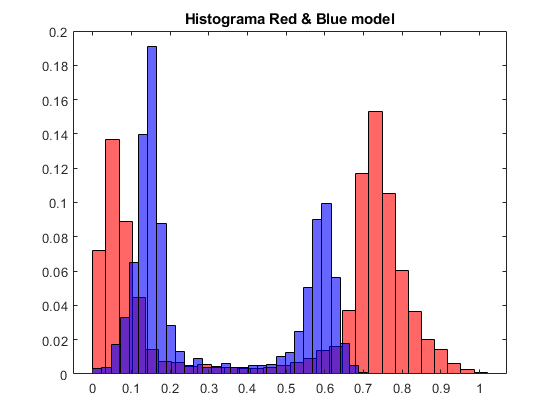


figure, [model_red, model_blue] = histRB(pattnorm, 30); title('Histograma Red & Blue model');

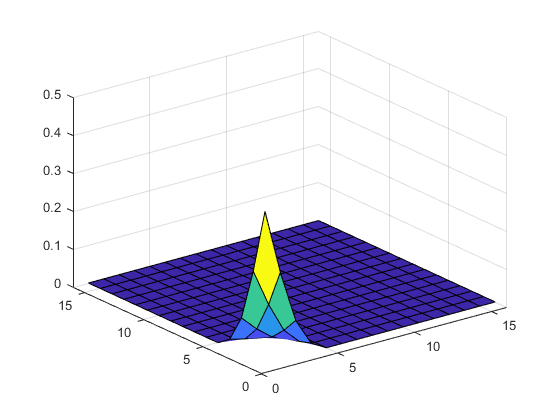


h1 = histo(pattnorm, 16);
h1 = imgaussfilt3(h1,1.5);
figure, surf(h1);

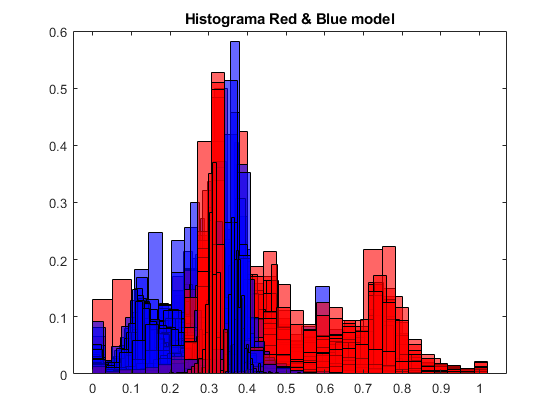


positive = imread('acmilan/04.jpg');
posnorm = normalizeRGB(positive);
figure, [red, blue] = histRB(pattnorm, 20); title('Histograma Red & Blue model');

index = 0;
red = 2;
blue = 2;


[red, blue] = computeQuadrants(model_red, model_blue, posnorm, 30, index, red, blue);